## 0. Initialize Parameters

n = 1251;                   % Number of locations to evaluate bridge failure
L = 1250;                   % Length of bridge
x = linspace(0, L, n);      % Define x coordinate
total_loads = zeros(1, n);  % Initialize total_loads for SFD(x)

## 1. Point Loading Analysis (SFD, BMD)

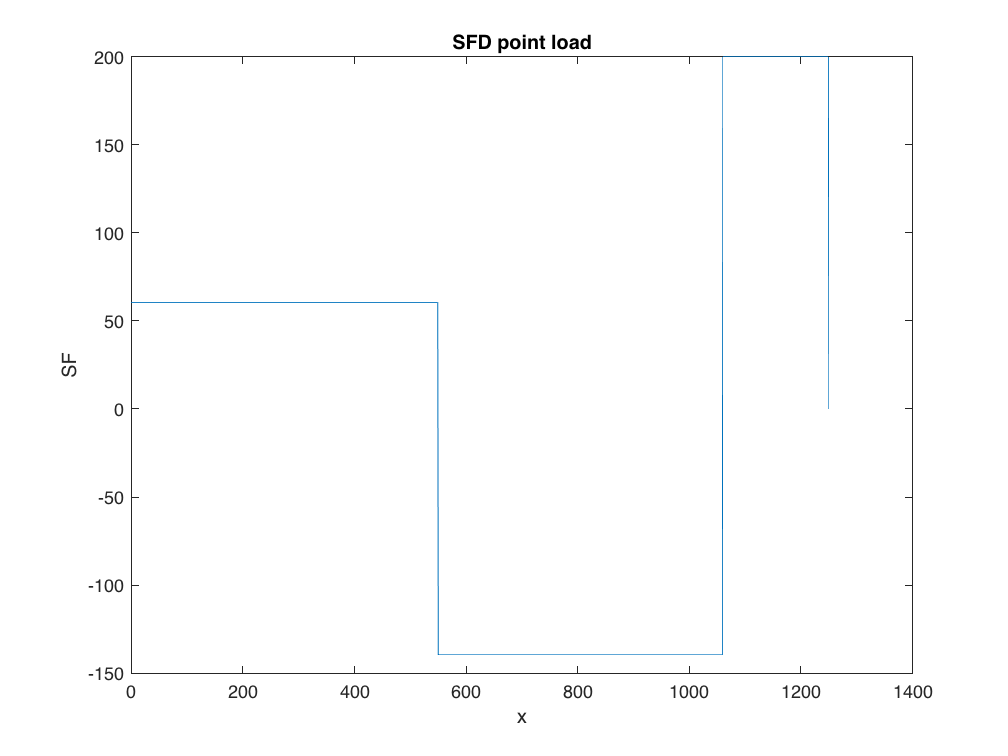

P = -200; % Point load(s) applied; change this variable
% Construct load vector
[SFD_PL, BMD_PL, total_loads] = ApplyPL(550, P, n, total_loads); 
[SFD_PL, BMD_PL, total_loads] = ApplyPL(L, P, n, total_loads); 
plot(x, SFD_PL)
xlabel('x')
ylabel('SF')
title('SFD point load')

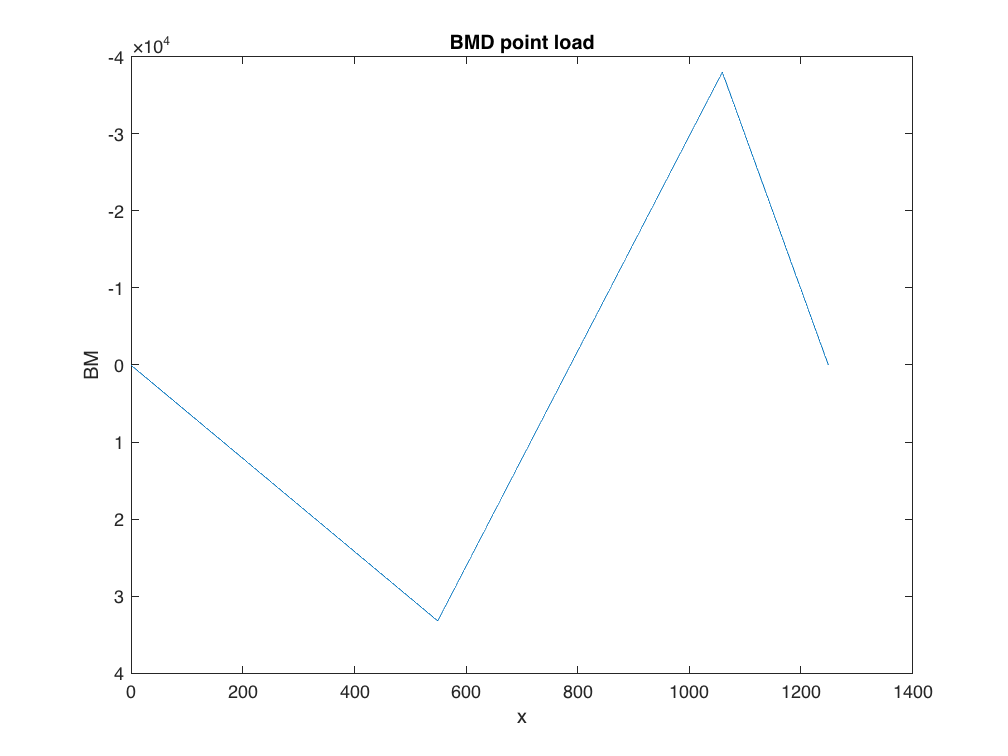

plot(x, BMD_PL)
xlabel('x')
ylabel('BM')
title('BMD point load')
set(gca, 'YDir', 'reverse')

## 1.1 Train Load

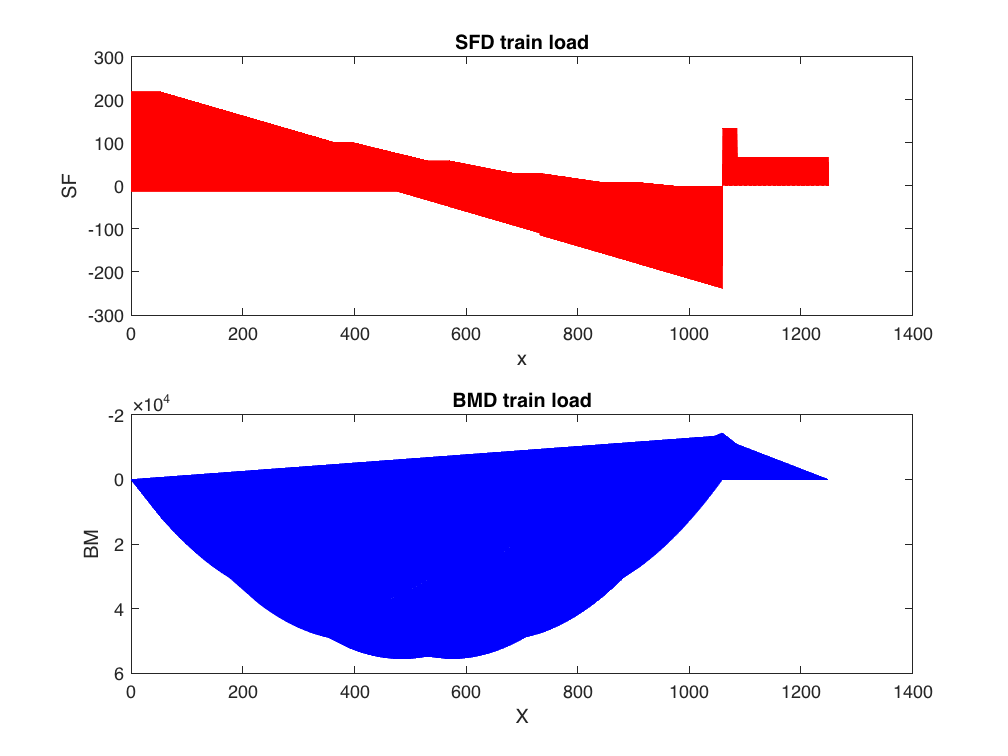

P = -400;
P_each = P/6; % Set train load as 6 point loads applied via the wheels
total_loads = zeros(1, n);
for n = 52:1250 % Define the location of the last wheel
    x0 = n;
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    % Define point load distances (distance between wheels)
    for i = 1:6
        if x_load(i) <= 1250
            [SFD_TL, BMD_TL, total_loads] = ApplyPL(x_load(i), P_each, n, ...
                total_loads);
            % Create SFD, BMD from train load
        end 
    end
    SFD_Total_TL(n-51,:) = SFD_TL; % Insert the data to a SF_matrix
    BMD_Total_TL(n-51,:) = BMD_TL;
% Reset variables for next train load case
SFD_TL = zeros(1,1251);
BMD_TL = zeros(1,1251);
total_loads = zeros(1,1251);
end
subplot(2,1,1)
plot(x,SFD_Total_TL,'red') % plot the SF_matrix against x
xlabel('x')
ylabel('SF')
title('SFD train load')
subplot(2,1,2)
plot(x,BMD_Total_TL,'blue') % plot the BM_matrix against x
xlabel('X')
ylabel('BM')
title('BMD train load')
set(gca, 'YDir', 'reverse')

% Get the outer bound for SF,BM
SF_TL_max = max(abs(SFD_Total_TL));
% Just need to consider the absolute value of shear force
% when calculating shear failure
BM_TL_max=max(BMD_Total_TL);
BM_TL_min=min(BMD_Total_TL);

## 2. Define Cross-Sections

% Left Cross Section (from start, x = 0, until x = 787)
xc = [0 15 16 549 550 787]; % Location, x, of cross-section change
tfb = [100 100 100 100 100 100]; % Top Flange Width
tft = [2.54 2.54 2.54 2.54 2.54 2.54]; % Top Flange Thickness
wh = [110 110 110 110 110 110]; % Web Height
wt = [1.27 1.27 1.27 1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
ws = [70 70 70 70 70 70]; % Web Spacing
bfb = [0 0 0 0 0 0]; % Bottom Flange Width
bft = [0 0 0 0 0 0]; % Bottom Flange Thickness
gtb = [10 10 10 10 10 10]; % Glue Tab Width
gtt = [1.27 1.27 1.27 1.27 1.27 1.27]; % Glue Tab Thickness
a = [30 30 260 260 160 160]; % Diaphragm Spacing

% Interpolate values across every mm of bridge
tfb = interp1(xc, tfb, x);
tft = interp1(xc, tft, x);
wh = interp1(xc, wh, x);
wt = interp1(xc, wt, x);
ws = interp1(xc, ws, x);
bfb = interp1(xc, bfb, x);
bft = interp1(xc, bft, x);
gtb = interp1(xc, gtb, x);
gtt = interp1(xc, gtt, x);
a = interp1(xc, a, x);

% Right Cross Section (from x = 788 to end, x = 1250)
xc_r = [788 989 990 1059 1060 1129 1130 L];
flh = [90 90 90 90 90 90 90 90]; % Top flap height
flt = [1.27 1.27 2.54 2.54 2.54 2.54 1.27 1.27]; % Top flap thickness
tfb_r = [100 100 100 100 100 100 100 100];
tft_r = [1.27 1.27 1.27 1.27 1.27 1.27 1.27 1.27];
wh_r = [110 110 110 110 110 110 110 110];
wt_r = [1.27 1.27 2.54 2.54 2.54 2.54 1.27 1.27];
ws_r = [75 75 75 75 75 75 75 75];
bfb_r = [75 75 75 75 75 75 75 75];
bft_r = [1.27 1.27 1.27 1.27 1.27 1.27 1.27 1.27];
gtb_r = [10 10 10 10 10 10 10 10];
gtt_r = [1.27 1.27 1.27 1.27 1.27 1.27 1.27 1.27];
a_r = [160 160 160 160 80 80 80 80];

% Interpolate values across every mm of bridge
flh = interp1(xc_r, flh, x);
flt = interp1(xc_r, flt, x);
tfb_r = interp1(xc_r, tfb_r, x);
tft_r = interp1(xc_r, tft_r, x);
wh_r = interp1(xc_r, wh_r, x);
wt_r = interp1(xc_r, wt_r, x);
ws_r = interp1(xc_r, ws_r, x);
bfb_r = interp1(xc_r, bfb_r, x);
bft_r = interp1(xc_r, bft_r, x);
gtb_r = interp1(xc_r, gtb_r, x);
gtt_r = interp1(xc_r, gtt_r, x);
a_r = interp1(xc_r, a_r, x);

% Calculate cross-section properties 
% (left and right side calculations done separately)
[ybot, ytop, I, Qcent, Qglue] = SectionPropertiesLeft (x, n, tfb,...
    tft, wh, wt, bfb, bft, gtb, gtt)

ybot =    83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484   83.0484


ytop =    29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916   29.4916


I = 	1.0e+05 *

    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157    7.2157


Qcent = 	1.0e+03 *

    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592    8.7592


Qglue = 	1.0e+03 *

    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683    7.1683


[ybot_r, ytop_r, I_r, Qcent_r, Qglue_r] = SectionPropertiesRight...
    (x, n, flh, flt, tfb_r, tft_r, wh_r, wt_r, bfb_r, bft_r, gtb_r, gtt_r)

ovheight =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


ybot_r =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


ytop_r =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


I_r = 	1.0e+07 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


Qcent_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


Qglue_r = 	1.0e+04 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


## 3. Define Material Properties

SigT = 30;  % Tensile strength
SigC = 6;   % Compressive strength
E = 4000;   % Young's Modulus
TauU = 4;   % Shear strength, matboard
TauG = 2;   % Shear strength, glue
mu = 0.2;   % Poisson's ratio

## 4. Calculate Failure Moments and Shear Forces

% Left Side
% 4.1 Matboard shear failure
% 4.2 Glue shear failure
bcent = 2 * wt;
bglue = (2 * gtb); % + bcent % without bcent assumes imperfect glue tab
[ V_MatFail, V_GlueFail ] = Vfail( Qcent, Qglue, bcent, bglue, I, TauU, TauG )

V_MatFail =   836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592  836.9592


V_GlueFail = 	1.0e+03 *

    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264



% 4.3 Matboard shear buckling failure
V_Buck = VfailBuck ( x, wh, wt, a, Qcent, bcent, I, E, mu )

V_Buck = 	1.0e+03 *

    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    6.9031    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634    0.5634



% 4.4 Matboard tension failure
M_MatT = MfailMatT( x, ybot, ytop, I, SigT, BMD_PL )

M_MatT = 	1.0e+05 *

    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066


M_MatT_TL_max = MfailMatT( x, ybot, ytop, I, SigT, BM_TL_max )

M_MatT_TL_max = 	1.0e+05 *

    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066    2.6066


M_MatT_TL_min = MfailMatT( x, ybot, ytop, I, SigT, BM_TL_min )

M_MatT_TL_min = 	1.0e+05 *

   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401   -7.3401



% 4.5 Matboard compression failure
M_MatC = MfailMatC( x, ybot, ytop, I, SigC, BMD_PL )

M_MatC = 	1.0e+05 *

    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680


M_MatC_TL_max = MfailMatC( x, ybot, ytop, I, SigC, BM_TL_max )

M_MatC_TL_max = 	1.0e+05 *

    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680


M_MatC_TL_min = MfailMatC( x, ybot, ytop, I, SigC, BM_TL_min )

M_MatC_TL_min = 	1.0e+04 *

   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131   -5.2131



% 4.6 Matboard flexural buckling failure
% Thin plate buckling for point load (left)
[ M_Buck1, M_Buck2, M_Buck3 ] = MfailBuck ( tft, tfb, wt, ws, bfb, bft,...
    I, ytop, ybot, E, mu, BMD_PL )

M_Buck1 = 	1.0e+05 *

    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547


M_Buck2 = 	1.0e+06 *

    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218


M_Buck3 = 	1.0e+06 *

    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171


% Thin plate buckling for maximum positive train load (left)
[ M_Buck1_TL_max, M_Buck2_TL_max, M_Buck3_TL_max ] = MfailBuck (tft, tfb,...
    wt, ws, bfb, bft, I, ytop, ybot, E, mu, BM_TL_max )

M_Buck1_TL_max = 	1.0e+05 *

    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547


M_Buck2_TL_max = 	1.0e+06 *

    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218


M_Buck3_TL_max = 	1.0e+06 *

    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171


% Thin plate buckling for maximum negative train load (left)
[ M_Buck1_TL_min, M_Buck2_TL_min, M_Buck3_TL_min ] = MfailBuck (tft, tfb,...
    wt, ws, bfb, bft, I, ytop, ybot, E, mu, BM_TL_min )

M_Buck1_TL_min =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck2_TL_min =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck3_TL_min = 	1.0e+04 *

   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778   -4.1778



% Right side
% 4.1 Matboard shear failure
% 4.2 Glue shear failure
bcent_r = 2 * wt_r;
bglue_r = (2 * gtb_r); % + bcent % without bcent, assumes imperfect glue tab
[ V_MatFail_r, V_GlueFail_r ] = Vfail( Qcent_r, Qglue_r, bcent_r, bglue_r,...
    I_r, TauU, TauG )

V_MatFail_r = 	1.0e+03 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


V_GlueFail_r = 	1.0e+03 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN



% 4.3 Matboard shear buckling failure
V_Buck_r = VfailBuck ( x, wh_r, wt_r, a_r, Qcent_r, bcent_r, I_r, E, mu )

V_Buck_r = 	1.0e+04 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN



% 4.4 Matboard tension failure
M_MatT_r = MfailMatT( x, ybot_r, ytop_r, I_r, SigT, BMD_PL )

M_MatT_r = 	1.0e+06 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_MatT_TL_max_r = MfailMatT( x, ybot_r, ytop_r, I_r, SigT, BM_TL_max )

M_MatT_TL_max_r = 	1.0e+06 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_MatT_TL_min_r = MfailMatT( x, ybot_r, ytop_r, I_r, SigT, BM_TL_min )

M_MatT_TL_min_r = 	1.0e+06 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


% 4.5 Matboard compression failure
M_MatC_r = MfailMatC( x, ybot_r, ytop_r, I_r, SigC, BMD_PL )

M_MatC_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_MatC_TL_max_r = MfailMatC( x, ybot_r, ytop_r, I_r, SigC, BM_TL_max )

M_MatC_TL_max_r = 	1.0e+06 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_MatC_TL_min_r = MfailMatC( x, ybot_r, ytop_r, I_r, SigC, BM_TL_min )

M_MatC_TL_min_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN



% 4.6 Matboard flexural buckling failure
% Thin plate buckling for point load
[ M_Buck1_r, M_Buck2_r, M_Buck3_r ] = MfailBuck ( tft_r, tfb_r, wt_r,...

M_Buck1_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_Buck2_r =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


M_Buck3_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


    ws_r, bfb_r, bft_r, I_r, ytop_r, ybot_r, E, mu, BMD_PL )
% Thin plate buckling for maximum positive train load (right)
[ M_Buck1_TL_max_r, M_Buck2_TL_max_r, M_Buck3_TL_max_r ] = MfailBuck (...
    tft_r, tfb_r, wt_r, ws_r, bfb_r, bft_r, I_r, ytop_r, ybot_r, E, mu,...
    BM_TL_max )

M_Buck1_TL_max_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_Buck2_TL_max_r = 	1.0e+06 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_Buck3_TL_max_r = 	1.0e+06 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


% Thin plate buckling for maximum negative train load (right)
[ M_Buck1_TL_min_r, M_Buck2_TL_min_r, M_Buck3_TL_min_r ] = MfailBuck ( ...
    tft_r, tfb_r, wt_r, ws_r, bfb_r, bft_r, I_r, ytop_r, ybot_r, E, mu,...
    BM_TL_min )

M_Buck1_TL_min_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


M_Buck2_TL_min_r =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


M_Buck3_TL_min_r = 	1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


                                             
% Reset left side variables on right (otherwise they'll be nan and I'll cry)
for i = 788:n
    M_MatT(i) = 0;
    M_MatC(i) = 0;
    V_MatFail(i) = 0;
    V_GlueFail(i) = 0;
    M_Buck1(i) = 0;
    M_Buck2(i) = 0;
    M_Buck3(i) = 0;
    V_Buck(i) = 0;
    M_MatT_TL_max(i) = 0;
    M_MatT_TL_min(i) = 0;
    M_MatC_TL_max(i) = 0;
    M_MatC_TL_min(i) = 0;
    M_Buck1_TL_max(i) = 0;
    M_Buck2_TL_max(i) = 0;
    M_Buck3_TL_max(i) = 0;
    M_Buck1_TL_min(i) = 0; 
    M_Buck2_TL_min(i) = 0;
    M_Buck3_TL_min(i) = 0;
end

% Reset right side variables on left
for i = 1:787
    M_MatT_r(i) = 0;
    M_MatC_r(i) = 0;
    V_MatFail_r(i) = 0;
    V_GlueFail_r(i) = 0;
    M_Buck1_r(i) = 0;
    M_Buck2_r(i) = 0;
    M_Buck3_r(i) = 0;
    V_Buck_r(i) = 0;
    M_MatT_TL_max_r(i) = 0;
    M_MatT_TL_min_r(i) = 0;
    M_MatC_TL_max_r(i) = 0;
    M_MatC_TL_min_r(i) = 0;
    M_Buck1_TL_max_r(i) = 0;
    M_Buck2_TL_max_r(i) = 0;
    M_Buck3_TL_max_r(i) = 0;
    M_Buck1_TL_min_r(i) = 0;
    M_Buck2_TL_min_r(i) = 0;
    M_Buck3_TL_min_r(i) = 0;
end

% Add left and ride side vectors together to get one cohesive 
% vector for whole bridge
M_MatT = M_MatT + M_MatT_r

M_MatT = 	1.0e+06 *

    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607


M_MatC = M_MatC + M_MatC_r

M_MatC = 	1.0e+05 *

    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680    1.4680


V_MatFail = V_MatFail + V_MatFail_r

V_MatFail = 	1.0e+03 *

    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370    0.8370


V_GlueFail = V_GlueFail + V_GlueFail_r

V_GlueFail = 1×1251
	1.0e+03 *

    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264    4.0264


M_Buck1 = M_Buck1 + M_Buck1_r

M_Buck1 = 1×1251
	1.0e+05 *

    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547


M_Buck2 = M_Buck2 + M_Buck2_r

M_Buck2 = 1×1251
	1.0e+06 *

    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218    1.0218


M_Buck3 = M_Buck3 + M_Buck3_r

M_Buck3 = 1×1251
	1.0e+06 *

    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171


V_Buck = V_Buck + V_Buck_r

V_Buck = 1×1251
	1.0e+04 *

    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.6903    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563    0.0563


M_MatT_TL_max = M_MatT_TL_max + M_MatT_TL_max_r

M_MatT_TL_max = 1×1251
	1.0e+06 *

    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607    0.2607


M_MatT_TL_min = M_MatT_TL_min + M_MatT_TL_min_r

M_MatT_TL_min = 1×1251
	1.0e+06 *

   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340   -0.7340


M_MatC_TL_max = M_MatC_TL_max + M_MatC_TL_max_r

M_MatC_TL_max = 1×1251
	1.0e+06 *

    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468    0.1468


M_MatC_TL_min = M_MatC_TL_min + M_MatC_TL_min_r

M_MatC_TL_min = 1×1251
	1.0e+05 *

   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213   -0.5213


M_Buck1_TL_max = M_Buck1_TL_max + M_Buck1_TL_max_r

M_Buck1_TL_max = 1×1251
	1.0e+05 *

    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547    4.7547


M_Buck2_TL_max = M_Buck1_TL_max + M_Buck1_TL_max_r

M_Buck2_TL_max = 1×1251
	1.0e+06 *

    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755    0.4755


M_Buck3_TL_max = M_Buck3_TL_max + M_Buck3_TL_max_r

M_Buck3_TL_max = 1×1251
	1.0e+06 *

    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171    1.1171


M_Buck1_TL_min = M_Buck1_TL_min + M_Buck1_TL_min_r

M_Buck1_TL_min = 1×1251
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck2_TL_min = M_Buck2_TL_min + M_Buck2_TL_min_r

M_Buck2_TL_min = 1×1251
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck3_TL_min = M_Buck3_TL_min + M_Buck3_TL_min_r

M_Buck3_TL_min = 1×1251
	1.0e+05 *

   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178   -0.4178


## 4.7 Calculate and Visualize Failure Loads

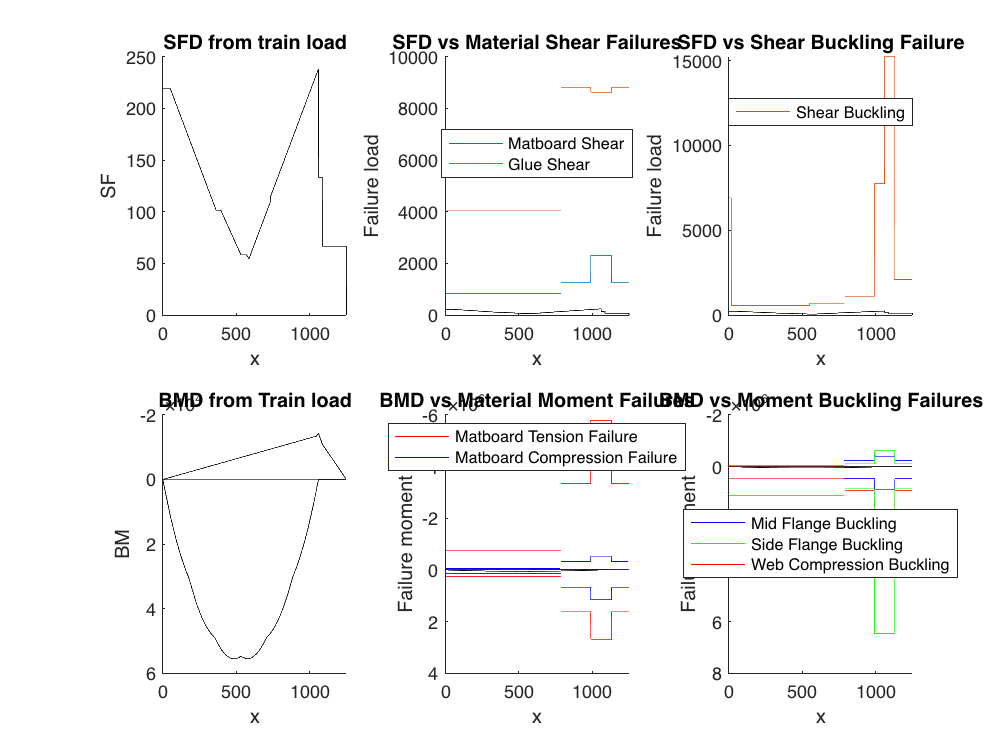

% Load Case 1
VisualizeTL(x, P, SF_TL_max, BM_TL_max, BM_TL_min, V_MatFail,...
    V_GlueFail, V_Buck, M_MatT_TL_max, M_MatT_TL_min, M_MatC_TL_max,...
    M_MatC_TL_min , M_Buck1_TL_max, M_Buck2_TL_max, M_Buck3_TL_max,...
    M_Buck1_TL_min, M_Buck2_TL_min, M_Buck3_TL_min)

[FOS_V,FOS_M] = FOSTL(SF_TL_max, BM_TL_max, BM_TL_min, V_MatFail, ...
    V_GlueFail, V_Buck, M_MatT_TL_max, M_MatT_TL_min, M_MatC_TL_max,...
    M_MatC_TL_min , M_Buck1_TL_max, M_Buck2_TL_max, M_Buck3_TL_max,...
    M_Buck1_TL_min, M_Buck2_TL_min, M_Buck3_TL_min)

FOS_V = 2.5744

FOS_M = 2.6436

% Load Case 2 (Point Loading)
% Calculate failure load for each mode of failure, then overall
Pf = FailLoad(V_MatFail, V_GlueFail, V_Buck, M_MatT, M_MatC, M_Buck1,...
    M_Buck2, M_Buck3)

P_V_MatFail = 1.1989e+03

P_V_GlueFail = 5.7676e+03

P_V_Buck = 1.0081e+03

P_M_MatT = 1.5699e+03

P_M_MatC = 884.1444

P_M_Buck1 = 1.6216e+03

P_M_Buck2 = 6.1539e+03

P_M_Buck3 = 702.8712

Pf = 702.8712

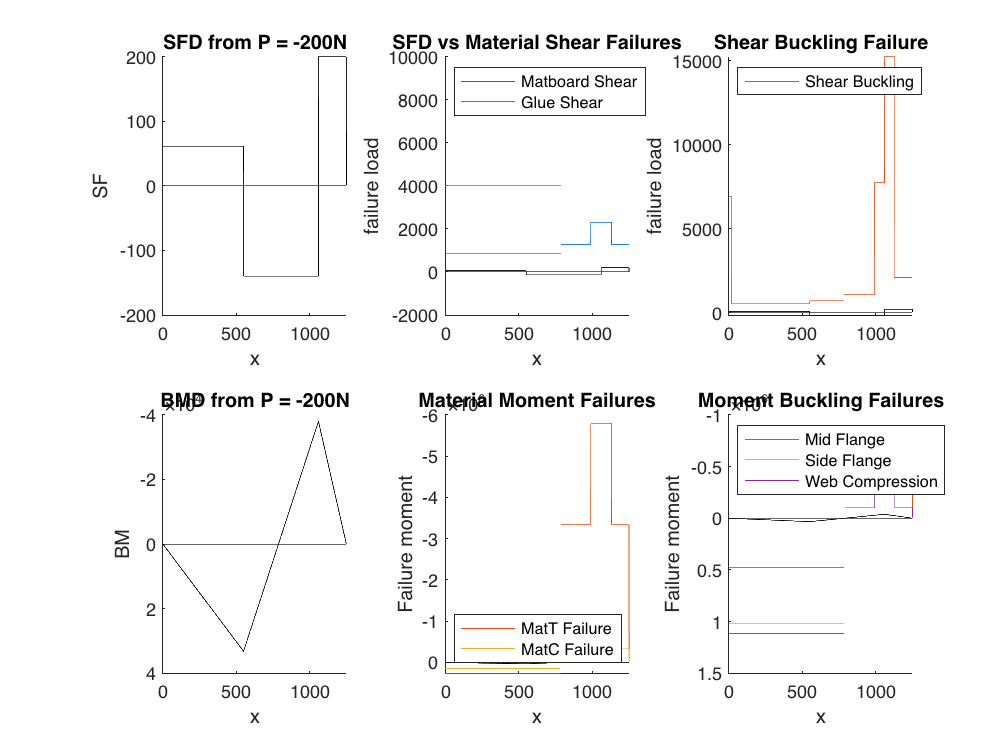

% Graph SFD, BMD vs failure shear forces/moments
VisualizePL(x, SFD_PL, BMD_PL, V_MatFail, V_GlueFail,...
    V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3, Pf);

## 5. Calculate mid-span deflection

% load case 2, P = -200N
Deflection = deflection(x, BMD_PL, E, I, I_r)

Deflection = 0.8665

## Function Definitions

function [ SFD_PL, BMD_PL, total_loads ] = ApplyPL( xP, P, n, total_loads )
% Constructs load vector from application of total point loads, 
% then SFD & BMD from total loads.
% Assumes fixed location of supports.
% xP = distance from left (A) support (x = 0)
    % Input: location and magnitude of point load. 
    % The previous load vector can be entered as input to 
    % construct the load vector of multiple point loads.
    % Output: SFD_PL, BMD_PL, total_loads: 1-D arrays of length n

xP_B = 1060;
cur_P_B = -P * xP / xP_B; % P_B due to current P
P_A = total_loads(1) -P - cur_P_B; % Overall P_A
P_B = cur_P_B + total_loads(xP_B+1); % Overall P_B

total_loads(1) = P_A;
total_loads(xP+1) = P;
if xP == xP_B
   total_loads(xP_B+1) = P_B + P;
else
    total_loads(xP_B+1) = P_B;
end

% Constructs SFD, BMD from all point loads applied.
SFD_PL = zeros(1, n);
SFD_PL(1) = total_loads(1);
    for i = 2:length(total_loads)
        SFD_PL(i) = total_loads(i) + SFD_PL(i-1);
    end
    BMD_PL = cumsum(SFD_PL);
    BMD_PL(n) = 0;
end


function [ ybot, ytop, I, Qcent, Qglue ] = SectionPropertiesLeft( ...
    x, n, tfb, tft, wh, wt, bfb, bft, gtb, gtt )
% Calculates sectional properties ybar, I and Q for left half.
    % Input: Cross-sectional properties, all 1-D arrays of length n
    % Output: Sectional Properties at every value of x. 
    % Each property is a 1-D array of length n

ovheight = tft + wh + bft; % Total height along beam

% Initialize A (area)
tfa = zeros(1, n);
bfa = zeros(1, n);
wa = zeros(1, n);
gta = zeros(1, n);

% Initialize I_0
tfI = zeros(1, n);
bfI = zeros(1, n);
wI = zeros(1, n);
gtI = zeros(1, n);

tfIsum = zeros(1, n);
bfIsum = zeros(1, n);
wIsum = zeros(1, n);
gtIsum = zeros(1, n);

% Initialize ybar & I
ybot = zeros(1, n);
ytop = zeros(1, n);
I = zeros(1, n);

% Initialize Q sum value(s), Qcent, Qglue
wQ = zeros(1, n);
Qcent = zeros(1, n);
Qglue = zeros(1, n);

for i = 1:length(x)
    % Areas, A
    tfa(i) = tfb(i) * tft(i);
    bfa(i) = bfb(i) * bft(i);
    wa(i) = 2 * wh(i) * wt(i); % Assumes 2 webs
    gta(i) = 2 * gtb(i) * gtt(i); % Assumes 2 glue tabs
    
    % Local centroids, y
    tfy = ovheight - (tft ./ 2);
    bfy = bft ./ 2;
    wy = (wh ./ 2) + bft;
    gty = ovheight(i) - tft(i) - (gtt ./ 2);

    % Global centroid, ybar
    ybot(i) = (tfa(i) * tfy(i) + bfa(i) * bfy(i) + wa(i) * wy(i) + ...
        gta(i) * gty(i)) / (tfa(i) + bfa(i) + wa(i) + gta(i));
    ytop(i) = abs(ybot(i) - ovheight(i));
    
    % I naught, I_0
    tfI(i) = (tfb(i) * (tft(i)^3)) / 12;
    bfI(i) = (bfb(i) * (bft(i)^3)) / 12;
    wI(i) = 2 * (wt(i) * (wh(i)^3)) / 12;
    gtI(i) = 2 * (gtb(i) * (gtt(i)^3)) / 12;

    tfIsum(i) = tfI(i) + tfa(i) * (abs(ybot(i) - tfy(i)))^2;
    bfIsum(i) = bfI(i) + bfa(i) * (abs(ybot(i) - bfy(i)))^2;
    wIsum(i) = wI(i) + wa(i) * (abs(ybot(i) - wy(i)))^2;
    gtIsum(i) = gtI(i) + gta(i) * (abs(ybot(i) - gty(i)))^2;

    % Second moment of area, I
    I(i) = tfIsum(i) + bfIsum(i) + wIsum(i) + gtIsum(i);

    % First moment of area, Q (Qcent & Qglue)
    wQ(i) = (2 * wt(i) * (ybot(i)-bft(i))) * ((ybot(i)-bft(i)) / 2);
    Qcent(i) = bfa(i) * (ybot(i)-(bft(i)/2)) + wQ(i);
    Qglue(i) = tfa(i) * (ovheight(i) - ybot(i) - tft(i) / 2);
end
end


function [ V_MatFail, V_GlueFail ] = Vfail( Qcent, Qglue, bcent, bglue, ...
    I, TauU, TauG )
% Calculates shear forces at every value of x that would 
% cause a matboard shear failure and a glue shear failure
    % Input: Sectional Properties (list of 1-D arrays), TauU & TauG 
    % (scalar material property)
    % Output: V_MatFail, V_GlueFail, both 1-D arrays of length n

V_MatFail = zeros(1, length(Qcent));
V_GlueFail = zeros(1, length(Qglue));

for i = 1:length(Qcent)
    V_MatFail(i) = TauU * I(i) * bcent(i) / Qcent(i);
    V_GlueFail(i) = TauG * I(i) * bglue(i) / Qglue(i);
end
end


function [ V_Buck ] = VfailBuck ( x, wh, wt, a, Qcent, bcent, I, E, mu )
% Calculates shear forces at every value of x that would 
% cause a shear buckling failure in the web
    % Input: Geometric & Sectional Properties Properties 
    % (lists of 1-D arrays), E, mu (material properties)
    % Output: V_Buck a 1-D array of length n

SigCrit = zeros(1, length(x));
V_Buck = zeros(1, length(x));

for i = 1:length(x)
    SigCrit(i) = ((5 * pi^2 * E) / (12 * (1 - mu^2))) * ...
        (((wt(i) / wh(i))^2) + ((wt(i) / a(i))^2));
    V_Buck(i) = SigCrit(i) * I(i) * bcent(i) / Qcent(i);
end
end


function [ M_MatT ] = MfailMatT( x, ybot, ytop, I, SigT, BMD )
% Calculates bending moments at every value of x that would cause 
% a matboard tension failure
    % Input: Sectional Properties (list of 1-D arrays), 
    % SigT (material property), BMD (1-D array)
    % Output: M_MatT (1-D array of length n)

M_MatT = zeros(1, length(x));

for i = 1:1251
    if BMD(i) > 0 % If moment is (+), tension failure will be at the bottom
        M_MatT(i) = SigT * I(i) / ybot(i);
    elseif BMD(i) < 0 % If moment is (-), tension failure will be at the top
        M_MatT(i) = -SigT * I(i) / ytop(i);
    end
end
end


function [ M_MatC ] = MfailMatC( x, ybot, ytop, I, SigC, BMD )
% Calculates bending moments at every value of x that would 
% cause a matboard compression failure
    % Input: Sectional Properties (list of 1-D arrays), 
    % SigC (material property), BMD (1-D array)
    % Output: M_MatC (1-D array of length n)

M_MatC = zeros(1, length(x));

for i = 1:length(x)
    if BMD(i) > 0 % If moment is (+), compression failure will be at the top
        M_MatC(i) = SigC * I(i) / ytop(i);
    elseif BMD(i) < 0 
        % If moment is (-), compression failure will be at the bottom
        M_MatC(i) = -SigC * I(i) / ybot(i);
    end
end
end


function [ M_Buck1, M_Buck2, M_Buck3 ] = MfailBuck ( tft, tfb, wt, ws, bfb, bft,...
    I, ytop, ybot, E, mu, BMD )
% Calculates bending moments at every value of x that would cause a 
% buckling failure
    % Input: Geometric & Sectional Properties (lists of 1-D arrays), 
    % E & mu (material properties), BMD (1-D array)
    % Output: M_Buck1, M_Buck2, M_Buck3 (1-D array of length n)

% Case 1 (M_Buck1): Flange between webs, k = 4
% Case 2 (M_Buck2): Flange tips, k = 0.425
% Case 3 (M_Buck3): Webs, k = 6
n = 1251;
M_Buck1 = zeros(1, n);
M_Buck2 = zeros(1, n);
M_Buck3 = zeros(1, n);

% Top in Compression
Sig1top = zeros(1, n); % Sigma crit for Middle flange
Sig2top = zeros(1, n); % Flange tips
Sig3top = zeros(1, n); % Sigma crit for webs
b1top = ws - (2 * wt); % Middle flange width 
b2top = (tfb - ws) / 2; % Flange tip width
b3top = ytop - tft; % Web height (above ybar)

% Bottom in Compression
Sig1bot = zeros(1, n); % Sigma crit for Middle flange 
Sig2bot = zeros(1, n); % Flange tips
Sig3bot = zeros(1, n); % Sigma crit for webs
b1bot = ws - (2 * wt); % Middle flange width
b2bot = (bfb - ws) / 2; % Flange tip width
b3bot = ybot - bft; % Web height (below ybar)

for i = 1:n
    if BMD(i) > 0 % Top in Compression
        Sig1top(i) = ((4 * pi^2 * E) / (12 * (1 - mu^2))) * ...
            (tft(i) / b1top(i))^2;
        Sig2top(i) = ((0.425 * pi^2 * E) / (12 * (1 - mu^2))) * ...
            (tft(i) / b2top(i))^2;
        Sig3top(i) = ((6 * pi^2 * E) / (12 * (1 - mu^2))) * (wt(i) / ...
            b3top(i))^2;
        M_Buck1(i) = Sig1top(i) * I(i) / ytop(i);
        M_Buck2(i) = Sig2top(i) * I(i) / ytop(i);
        M_Buck3(i) = Sig3top(i) * I(i) / ytop(i);

    elseif BMD(i) < 0 % Bottom in Compression
        Sig1bot(i) = ((4 * pi^2 * E) / (12 * (1 - mu^2))) * (bft(i) /...
            b1bot(i))^2;
        Sig2bot(i) = ((0.425 * pi^2 * E) / (12 * (1 - mu^2))) * (bft(i) /...
            b2bot(i))^2;
        Sig3bot(i) = ((6 * pi^2 * E) / (12 * (1 - mu^2))) * (wt(i) / b3bot(i))^2;
        M_Buck1(i) = -Sig1bot(i) * I(i) / ybot(i);
        M_Buck2(i) = -Sig2bot(i) * I(i) / ybot(i);
        M_Buck3(i) = -Sig3bot(i) * I(i) / ybot(i);
    end  
end
end


function [ Pf ] = FailLoad(V_MatFail, V_GlueFail, V_Buck, M_MatT, ...
    M_MatC, M_Buck1, M_Buck2, M_Buck3 )
% Calculates the magnitude of the load P that will cause one of
% the failure mechanisms to occur
    % Input: SFD, BMD under the currently applied points loads (P) 
    % (each 1-D array of length n)
    % {V_Mat, V_Glue, … M_MatT, M_MatC, … } (each 1-D array of length n)
    % Output: Failure Load value Pf
n = 1251;
P_local = -1; % create a dummy load
total_loads = zeros(1, n);
% get the SFD, BMD for the dummy load

[SFD_PL_local, BMD_PL_local, total_loads] = ApplyPL(550, P_local, n, ...
    total_loads);
[SFD_PL_local, BMD_PL_local, total_loads] = ApplyPL(1250, P_local, n, ...
    total_loads);
% calculate the ratio for failure load to dummy load
% choose the minimum ratio for each failure situation
P_V_MatFail = min(abs(V_MatFail ./ SFD_PL_local))
P_V_GlueFail = min(abs(V_GlueFail ./ SFD_PL_local))
P_V_Buck = min(abs(V_Buck ./ SFD_PL_local))
P_M_MatT = min(abs(M_MatT ./ BMD_PL_local))
P_M_MatC = min(abs(M_MatC ./ BMD_PL_local))
P_M_Buck1 = min(abs(M_Buck1 ./ BMD_PL_local))
P_M_Buck2 = min(abs(M_Buck2 ./ BMD_PL_local))
P_M_Buck3 = min(abs(M_Buck3 ./ BMD_PL_local))
% find the minimum among the ratio, as dummy force = 1N
% failure load = 1*smallest ratio
Pf = min([P_V_MatFail,P_V_GlueFail,P_V_Buck,P_M_MatT,P_M_MatC,...
    P_M_Buck1,P_M_Buck2,P_M_Buck3]);
end


function [] = VisualizePL(x, SFD, BMD, V_MatFail, V_GlueFail, V_Buck,...
    M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3, Pf)
% Graph SFD, BMD, and all failure shear forces & bending moments of 
% the bridge design
    % Input: SFD, BMD, failure shear forces & moments (all 1-D arrays 
    % of length n)
    % Output: 2x3 grid of plots; top row is shear force diagrams, bottom is
    % bending moment
figure;

subplot(2, 3, 1)
hold on
title("SFD from P = -200N")
plot(x, SFD, 'k')
xlabel('x')
ylabel('SF')
yline(0)
hold off

subplot(2, 3, [2,2,2])
hold on
title("SFD vs Material Shear Failures")
xlabel('x')
ylabel('failure load')
plot(x, V_MatFail)
plot(x, V_GlueFail)
plot(x, SFD, 'k')
yline(0)
legend('Matboard Shear', 'Glue Shear', '', 'Location', 'northwest')
hold off

subplot(2, 3, [3,3])
hold on
title("Shear Buckling Failure")
xlabel('x')
ylabel('failure load')
plot(x, SFD, 'k')
plot(x, V_Buck)
yline(0)
legend('', 'Shear Buckling', 'Location', 'northwest')
hold off

subplot(2, 3, 4)
hold on
title("BMD from P = -200N")
xlabel('x')
set(gca, 'YDir', 'reverse')
ylabel('BM')
plot(x, BMD, 'k')
yline(0)
hold off

subplot(2, 3, [5,5,5])
hold on
title("Material Moment Failures")
xlabel('x')
ylabel('Failure moment')
set(gca, 'YDir', 'reverse')
plot(x, BMD, 'k')
plot(x, M_MatT)
plot(x, M_MatC)
yline(0)
legend('', 'MatT Failure', 'MatC Failure', 'Location', 'southwest')
hold off

subplot(2, 3, [6,6,6,6])
hold on
title("Moment Buckling Failures")
xlabel('x')
ylabel('Failure moment')
set(gca, 'YDir', 'reverse')
plot(x, BMD, 'k')
plot(x, M_Buck1)
plot(x, M_Buck2)
plot(x, M_Buck3)
yline(0)
legend('', 'Mid Flange', 'Side Flange', 'Web Compression', 'Location', ...
    'northwest')
hold off
end


function [ ybot, ytop, I, Qcent, Qglue ] = SectionPropertiesRight ( x, n,...
    flh, flt, tfb_r, tft_r, wh_r, wt_r, bfb_r, bft_r, gtb_r, gtt_r )
% % Calculates sectional properties ybar, I and Q for right half.
    % Input: Cross-sectional properties, all 1-D arrays of length n
    % Output: Sectional Properties at every value of x. Each property is
    % a 1-D array of length n

ovheight = tft_r + wh_r + bft_r + flh % Total height along beam

% Initialize A
tfa = zeros(1, n);
bfa = zeros(1, n);
wa = zeros(1, n);
gta = zeros(1, n);
fla = zeros(1, n);

% Initialize I_0
tfI = zeros(1, n);
bfI = zeros(1, n);
wI = zeros(1, n);
gtI = zeros(1, n);
flI = zeros(1, n);

tfIsum = zeros(1, n);
bfIsum = zeros(1, n);
wIsum = zeros(1, n);
gtIsum = zeros(1, n);
flIsum = zeros(1, n);

% Initialize ybar, I
ybot = zeros(1, n);
ytop = zeros(1, n);
I = zeros(1, n);

% Initialize Q sum value(s), Qcent, Qglue
wQ = zeros(1, n);
Qcent = zeros(1, n);
Qglue = zeros(1, n);

for i = 1:length(x)
    % Areas, A
    fla(i) = 2 * flh(i) * flt(i); % 2 flaps
    tfa(i) = tfb_r(i) * tft_r(i); % Assumes all values have been 
    % interpolated already
    bfa(i) = bfb_r(i) * bft_r(i);
    wa(i) = 2 * wh_r(i) * wt_r(i); % Assumes 2 webs
    gta(i) = 2 * gtb_r(i) * gtt_r(i); % Assumes 2 glue tabs
    
    % Local centroids, y
    fly = ovheight(i) - tft_r(i) + (flh ./ 2);
    tfy = ovheight - (tft_r ./ 2);
    bfy = bft_r ./ 2;
    wy = (wh_r ./ 2) + bft_r;
    gty = ovheight(i) - tft_r(i) - (gtt_r ./ 2);

    % Global centroid, ybar
    ybot(i) = (fla(i) * fly(i) + tfa(i) * tfy(i) + bfa(i) * bfy(i) + ...
        wa(i) * wy(i) + gta(i) * gty(i)) / (fla(i) + tfa(i) + bfa(i) +...
        wa(i) + gta(i));
    ytop(i) = abs(ybot(i) - ovheight(i));
    
    % I naught, I_0
    flI(i) = 2 * (flt(i) * (flh(i)^3)) / 12;
    tfI(i) = (tfb_r(i) * (tft_r(i)^3)) / 12;
    bfI(i) = (bfb_r(i) * (bft_r(i)^3)) / 12;
    wI(i) = 2 * (wt_r(i) * (wh_r(i)^3)) / 12;
    gtI(i) = 2 * (gtb_r(i) * (gtt_r(i)^3)) / 12;

    flIsum(i) = flI(i) + fla(i) * (abs(ybot(i) - fly(i)))^2;
    tfIsum(i) = tfI(i) + tfa(i) * (abs(ybot(i) - tfy(i)))^2;
    bfIsum(i) = bfI(i) + bfa(i) * (abs(ybot(i) - bfy(i)))^2;
    wIsum(i) = wI(i) + wa(i) * (abs(ybot(i) - wy(i)))^2;
    gtIsum(i) = gtI(i) + gta(i) * (abs(ybot(i) - gty(i)))^2;

    % Second moment of area, I
    I(i) = flIsum(i) + tfIsum(i) + bfIsum(i) + wIsum(i) + gtIsum(i);

    % First moment of area, Q (Qcent & Qglue)
    wQ(i) = (2 * wt_r(i) * (ybot(i)-bft_r(i))) * ((ybot(i) - (bft_r(i)) / 2));
    Qcent(i) = bfa(i) * (ybot(i)-(bft_r(i)/2)) + wQ(i);
    Qglue(i) = tfa(i) * (tfy(i) - ybot(i)) + fla(i) * (fly(i) - ybot(i));
end
end


function [] = VisualizeTL(x, P, SFD, BMD_max, BMD_min, V_MatFail, ...
    V_GlueFail, V_Buck, M_MatT_max, M_MatT_min, M_MatC_max, M_MatC_min ,...
    M_Buck1_TL_max, M_Buck2_TL_max, M_Buck3_TL_max,M_Buck1_TL_min, ...
    M_Buck2_TL_min, M_Buck3_TL_min)
figure;

subplot(2, 3, 1)
hold on
title("SFD from train load")
xlabel('x')
ylabel('SF')
plot(x, SFD, 'k')
yline(0)
hold off

subplot(2, 3, [2,2,2])
hold on
title("SFD vs Material Shear Failures")
xlabel('x')
ylabel('Failure load')
plot(x, V_MatFail)
plot(x, V_GlueFail)
plot(x, SFD, 'k')
yline(0)
legend('Matboard Shear', 'Glue Shear', '', 'Location', 'best')
hold off

subplot(2, 3, [3,3])
hold on
title("SFD vs Shear Buckling Failure")
xlabel('x')
ylabel('Failure load')
plot(x, SFD, 'k')
plot(x, V_Buck)
yline(0)
legend('', 'Shear Buckling', 'Location', 'best')
hold off

subplot(2, 3, 4)
hold on
title("BMD from Train load")
set(gca, 'YDir', 'reverse')
xlabel('x')
ylabel('BM')
plot(x, BMD_max, 'k')
plot(x, BMD_min, 'k')
yline(0)
hold off

subplot(2, 3, [5,5,5])
hold on
set(gca, 'YDir', 'reverse')
title("BMD vs Material Moment Failures")
xlabel('x')
ylabel('Failure moment')
plot(x, BMD_max, 'k')
plot(x, BMD_min, 'k')
plot(x, M_MatT_max,'red',x, M_MatT_min,'red')
plot(x, M_MatC_max,'blue',x, M_MatC_min,'blue')
yline(0)
legend('','', 'Matboard Tension Failure', '','Matboard Compression Failure',...
    'Location', 'best')
hold off

subplot(2, 3, [6,6,6,6])
hold on
title("BMD vs Moment Buckling Failures")
xlabel('x')
ylabel('Failure moment')
set(gca, 'YDir', 'reverse')
plot(x, BMD_max, 'k')
plot(x, BMD_min, 'k')
plot(x, M_Buck1_TL_max,'blue',x, M_Buck2_TL_max,'red',x, M_Buck3_TL_max,'green')
plot(x, M_Buck1_TL_min,'blue',x, M_Buck2_TL_min,'red',x, M_Buck3_TL_min,'green')
yline(0)
legend('','', 'Mid Flange Buckling','', 'Side Flange Buckling','',...
    'Web Compression Buckling', 'Location', 'best')
hold off

end


function [ FOS_V,FOS_M ] = FOSTL(SF_TL_max, BM_TL_max, BM_TL_min, V_MatFail,...
    V_GlueFail, V_Buck, M_MatT_TL_max, M_MatT_TL_min, M_MatC_TL_max,...
    M_MatC_TL_min , M_Buck1_TL_max, M_Buck2_TL_max, M_Buck3_TL_max,...
    M_Buck1_TL_min, M_Buck2_TL_min, M_Buck3_TL_min)
% Calculate the FOS of each failure type by devided the capacity with real
% SF/BM and get the minimum ratio for each case
FOS_V_MATFAIL   = min(V_MatFail ./ SF_TL_max);
FOS_V_GlueFail  = min(V_GlueFail ./ SF_TL_max);
FOS_V_Buck      = min(V_Buck ./ SF_TL_max);
FOS_M_MATT_max  = min(M_MatT_TL_max ./ BM_TL_max);
FOS_M_MATT_min  = min(M_MatT_TL_min ./ BM_TL_min);
FOS_M_MATC_max  = min(M_MatC_TL_max ./ BM_TL_max);
FOS_M_MATC_min  = min(M_MatC_TL_min ./ BM_TL_min);
FOS_M_Buck1_max = min(M_Buck1_TL_max./ BM_TL_max);
FOS_M_Buck2_max = min(M_Buck2_TL_max./ BM_TL_max);
FOS_M_Buck3_max = min(M_Buck3_TL_max./ BM_TL_max);
FOS_M_Buck1_min = min(M_Buck1_TL_min./ BM_TL_min);
FOS_M_Buck2_min = min(M_Buck2_TL_min./ BM_TL_min);
FOS_M_Buck3_min = min(M_Buck3_TL_min./ BM_TL_min);
% put the result 13 situations into V_vector and M_vector
Res_V = [FOS_V_MATFAIL,FOS_V_GlueFail,FOS_V_Buck];
Res_M = [FOS_M_MATT_max,FOS_M_MATT_min,FOS_M_MATC_max,FOS_M_MATC_min,...
    FOS_M_Buck1_max,FOS_M_Buck2_max,FOS_M_Buck3_max,FOS_M_Buck1_min,...
    FOS_M_Buck2_min,FOS_M_Buck3_min];
% calculate FOS_V
FOS_V = min(Res_V);
FOS_M = 10000; % create a big value (initialize)

for i=1:10
    if Res_M(i) ~= 0 % avoid situation where FOS = 0
        if Res_M(i) < FOS_M
            FOS_M = Res_M(i);
        end
    end
end
end


function [deflection] = deflection(x, BMD, E, I, I_r)
% Calculate the deflection of the beam at the midspan between the two supports
% Input: BMD from -200 N point loads, E (material property), 
% I & I_r (sectional property)
% Output: Deflection (scalar)
% Caculate Phi
phi = BMD ./ E ./ I;
phi_r = BMD ./ E ./ I_r;
% Initialize delta value
delta_BA = 0;
delta_midA = 0;
for i = 1:788
    delta_BA = delta_BA + phi(i).*(1061-x(i));
    % integrating using for loop (left part)
end
for i = 789:1061
    delta_BA = delta_BA + phi_r(i).*(1061-x(i));
    % integrating using for loop (right part)
end
for i = 1:530
    delta_midA = delta_midA + phi(i).*(530-x(i));
    % integrating using for loop
end

deflection = 0.5*delta_BA - delta_midA; % Find deflection
end